## Чтение численных экспериментальных данных из XLSX

clear all
filename = 'plots_forces_moments_blood.xlsx';
sheet = 1;
%xlRange='A3:K43'; %вся таблица

%Выбор строк
RPMRange = 'A3:A43';
MassFlowRange = 'B3:B43';
PressureDeltaRange = 'C3:C43';

% MassFlowRange2 = 'B8:B43';
% PressureDeltaRange2 = 'C8:C43';
%Чтение столбцов и строк из таблицы
%subsetAll = xlsread(filename,sheet,xlRange);
RPM = xlsread(filename,sheet,RPMRange);   %Скорость вращения, [об/мин]
MassFlow = xlsread(filename,sheet,MassFlowRange);   %Массовый расход, [кг/с]
% MassFlow2 = xlsread(filename,sheet,MassFlowRange2);   %Массовый расход, [кг/с]
PressureDelta = xlsread(filename,sheet,PressureDeltaRange); %Перепад давления, [мм рт.ст.]
% PressureDelta2 = xlsread(filename,sheet,PressureDeltaRange2); %Перепад давления, [мм рт.ст.]

## Извлечение данных, согласно перепадам

RPM0 = zeros(7,1);  %задали нулевой вектор размерностью 7х1
rowCount=size(RPM,1);

for i = 6:6:size(RPM)   %заполнение его согласно таблице
    RPM0(i,1)=RPM(i,1);
end
%Взяли ненулевые значения
RPM1 = RPM0(RPM0 ~=0)

%Расход 1л/мин = 0,0175 кг/c
%RPM1 = [RPM(1) RPM(6) RPM(12) RPM(18) RPM(24) RPM(30) RPM(36)];

for j = 6:1:11 %для каждого из всех оборотов/расходов за исключением 6000 оборотов
%заполнение согласно таблице
%Инициализация
RPM0 = zeros(7,1);  

Fx0 = zeros(7,1);%задали нулевой вектор размерностью 7х1
Fy0 = Fx0;

MassFlow0 = Fx0;
PressureDelta0 = Fx0;

    for i = j:6:rowCount   % берем значения начиная с 7500 (6 ая строка)
        RPM0(i,1)=RPM(i,1);
        MassFlow0(i,1)=MassFlow(i,1);
        PressureDelta0(i,1)=PressureDelta(i,1);
    end

%Выбрали ненулевые значения зависимости от расходов (для каждого из
%расходов)
RPM_comb = RPM0(RPM0 ~= 0);

MassFlow_comb{j} = MassFlow0(MassFlow0 ~= 0);
PressureDelta_comb{j} = PressureDelta0(PressureDelta0 ~=0);
end 


% subplot(2,2,2)
% title('F_y')
xlabel('Массовый расход')
ylabel('Перепад давления, мм рт.ст.')
% legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")
% for j = 6:1:11
% %     PressureDelta_comb{j}
%     plot(MassFlow_comb{j},PressureDelta_comb{j})
% end
Q = linspace(1,6,6);
% A = MassFlow_comb{1,7}(1)
% B = PressureDelta_comb{1,7}(1)
for  j = 6:1:11
    for i = 1:6
        j1=j-5;
        MassFlow_comb_new{1,j1}(i)=MassFlow_comb{1,j}(i);
        PressureDelta_comb_new{1,j1}(i)=PressureDelta_comb{1,j}(i);
%         hold on
%         plot(MassFlow_comb{1,j}(i),PressureDelta_comb{1,j}(i),'--o')
        
    end
    
end


% PressureDelta_comb_new{1,1}(1)
% PressureDelta_comb_new{1,2}(1)
% PressureDelta_comb_new{1,3}(1)
for i = 1:6
    for j = 1:6
    PressDelt{j,i} = PressureDelta_comb_new{1,i}(j);
    MassFl{j,i} = MassFlow_comb_new{1,i}(j);
%     PressDelt{2,i} = PressureDelta_comb_new{1,i}(2)
    end
end
PD = cell2mat(PressDelt)
MFL = cell2mat(MassFl)
for i=1:6
    hold on
    plot(Q,PD(i,:))
    % Интерполировать по расходу
    
end
save('deltaPressureFlow.mat', "PD","MFL","Q")


clear all
load('deltaPressureFlow.mat');
% xData_save = zeros(6);
% yData_save = zeros(6);
for i=1:6

%     legend({'7500','9000','10500','12000','13500','15000'},"Location","best")
%     plot(Q,PD(i,:))
%     hold off
i
    xlabel(' л/мин')
    ylabel('Перепад давления')
    % Интерполировать по расходу и по перепадам давления
    [xData, yData] = prepareCurveData( Q, PD(i,:) );
    % Set up fittype and options.
% ft = fittype( 'cubicinterp' );
ft{i} = fittype('poly2');
% opts = fitoptions( 'Method','CubicSplineInterpolant');
% % opts.Display = 'Off';
% opts.Normalize = 'on';
% % opts.StartPoint = [0 0 0 2.17655923708106];

% Fit model to data.
[fitresult{i}, gof] = fit( xData, yData, ft{i} );
% hold on
% Plot fit with data.
figure( 'Name', 'FIT' );
%  xData_save(i) = xData; %6x1
yData_save{i} = yData; %6x1
h{i} = plot( fitresult{i}, xData, yData);
% legend( h, 'PD vs. MFL', 'FourierFit1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% % Label axes
% xlabel( 'MFL', 'Interpreter', 'none' );
% ylabel( 'PD', 'Interpreter', 'none' );
grid on
end

save('fittedResult.mat',"yData_save","fitresult","xData");

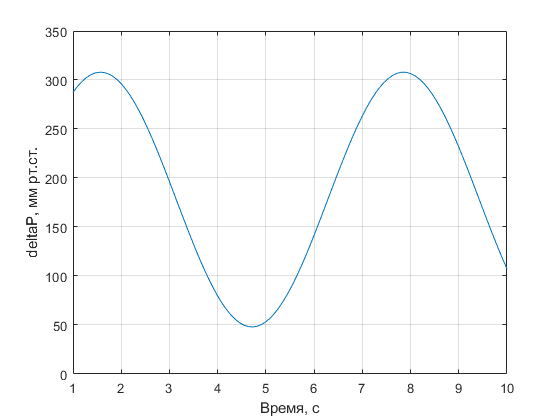

clear all
load('fittedResult.mat');
% for i=1:6
%     i
%     hold on
%     plot(fitresult{i},xData,yData_save{i});
%     grid on  
%     hold off    
% end
yDataArr = cell2mat(yData_save); %6x6
xDataArr = zeros(6);
for i =1:6
xDataArr(:,i) = xData;   
end

T=linspace(1,10);
deltaP = 130*sin(T)+178;
plot(T,deltaP)
xlabel('Время, с')
ylabel('deltaP, мм рт.ст.')
grid on

% for i=1:6
%     for j= 1:6
%         for k = 1:length(deltaP)
%         if (deltaP(k)-yDataArr(i,j)<10)
%             saveDP{i,j} = yDataArr(i,j);
%         end
%         end
%     end
% end
% DP_near = cell2mat(saveDP)

DP_near =    91.2150  133.1670  184.5440  244.9890  314.8860  394.1120
   90.6549  134.5630  187.7070  248.6460  317.6030  395.4370
   87.3734  131.8450  184.9070  244.9540  316.7650  398.1550
   78.3816  122.4850  176.4710  240.1380  312.4500  392.8470
   65.1852  109.8980  161.8650  225.3710  298.1400  381.6380
   41.8016   92.9244  146.0380  205.8730  277.7620  362.0520


    
    % for i=1:6
%     i
%     hold on
%     plot(fitresult{i},xData,yData_save{i});
%     grid on  
%     hold off    
% end

% plot(xDataArr, yDataArr)
% plot(fitresult, xData, yData_save);

% [xData, yData] = prepareCurveData( xDataArr, yDataArr );
% ft = fittype('lowess');
% [fitresult, gof] = fit( xData, yData, ft );
% h = plot( fitresult, xData, yData);